clear
bass = matfile('data_bass.mat')

bass =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_bass.mat'
            Properties.Writable: false                                                                  
    Properties.ProtectedLoading: false                                                                  
                    circularity: [1x15 double]                                                          
                    compactness: [1x15 double]                                                          
                     elongation: [1x15 double]                                                          
                          holes: [1x15 double]                                                          
                      intensity: [1x15 double]                                                          
                        thiness: [1x15 double]                            

guitar = matfile('data_guitar.mat')

guitar =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_guitar.mat'
            Properties.Writable: false                                                                    
    Properties.ProtectedLoading: false                                                                    
                    circularity: [1x15 double]                                                            
                    compactness: [1x15 double]                                                            
                     elongation: [1x15 double]                                                            
                          holes: [1x15 double]                                                            
                      intensity: [1x15 double]                                                            
                        thiness: [1x15 double]          

trumpet = matfile('data_trumpet.mat')

trumpet =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_trumpet.mat'
            Properties.Writable: false                                                                     
    Properties.ProtectedLoading: false                                                                     
                    circularity: [1x15 double]                                                             
                    compactness: [1x15 double]                                                             
                     elongation: [1x15 double]                                                             
                          holes: [1x15 double]                                                             
                      intensity: [1x15 double]                                                             
                        thiness: [1x15 double] 

drumm = matfile('data_drumm.mat')

drumm =   matlab.io.MatFile

  Properties:
              Properties.Source: 'C:\Users\mikip\Documents\Fag_Perception\Workshop\matlab\data_drumm.mat'
            Properties.Writable: false                                                                   
    Properties.ProtectedLoading: false                                                                   
                    circularity: [1x15 double]                                                           
                    compactness: [1x15 double]                                                           
                     elongation: [1x15 double]                                                           
                          holes: [1x15 double]                                                           
                      intensity: [1x15 double]                                                           
                        thiness: [1x15 double]                   

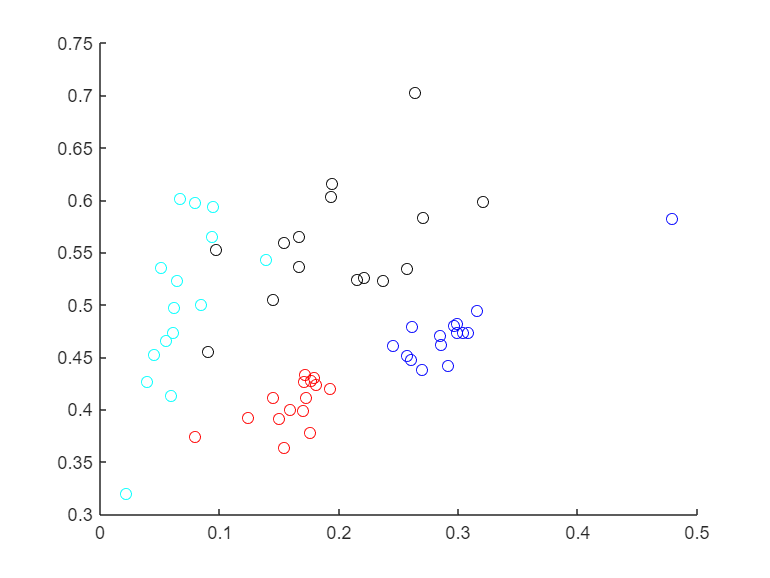


scatter(bass.circularity,bass.compactness,'red')
hold on
scatter(guitar.circularity,guitar.compactness,'blue')
scatter(trumpet.circularity,trumpet.compactness,'black')
scatter(drumm.circularity,drumm.compactness,'c')
hold off

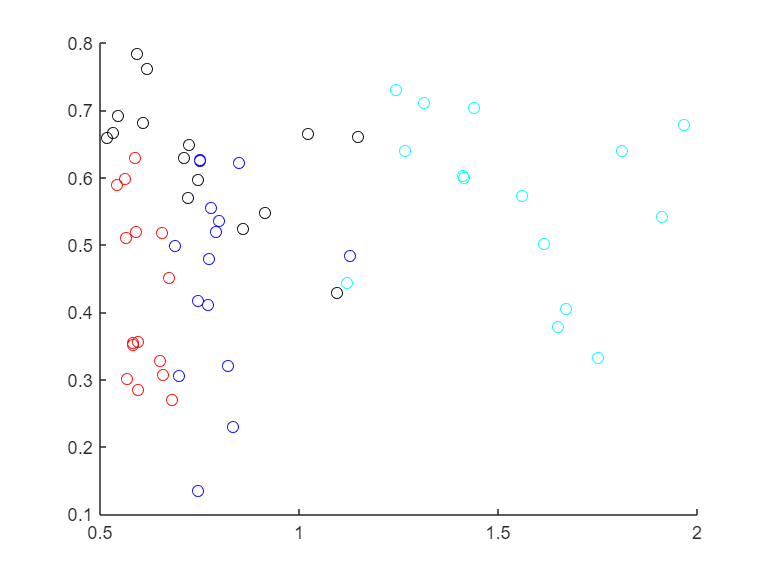


scatter(bass.elongation,bass.intensity,'red')
hold on
scatter(guitar.elongation,guitar.intensity,'blue')
scatter(trumpet.elongation,trumpet.intensity,'black')
scatter(drumm.elongation,drumm.intensity,'c')
hold off

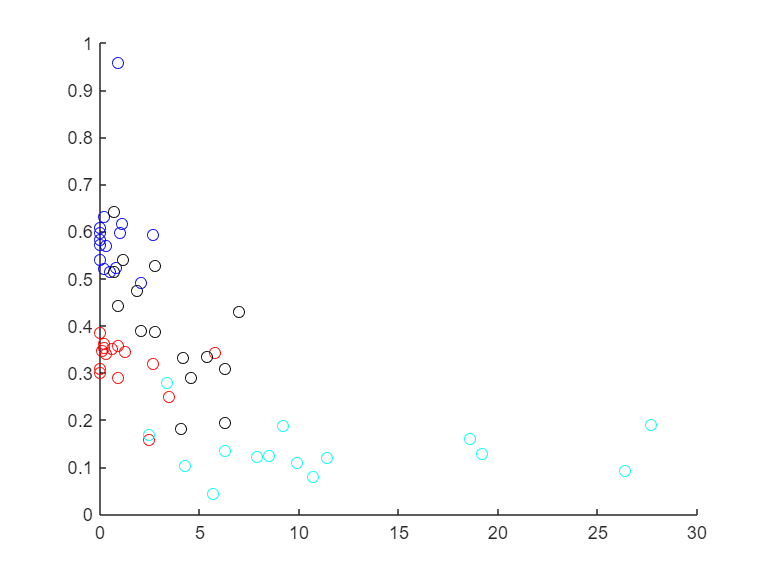

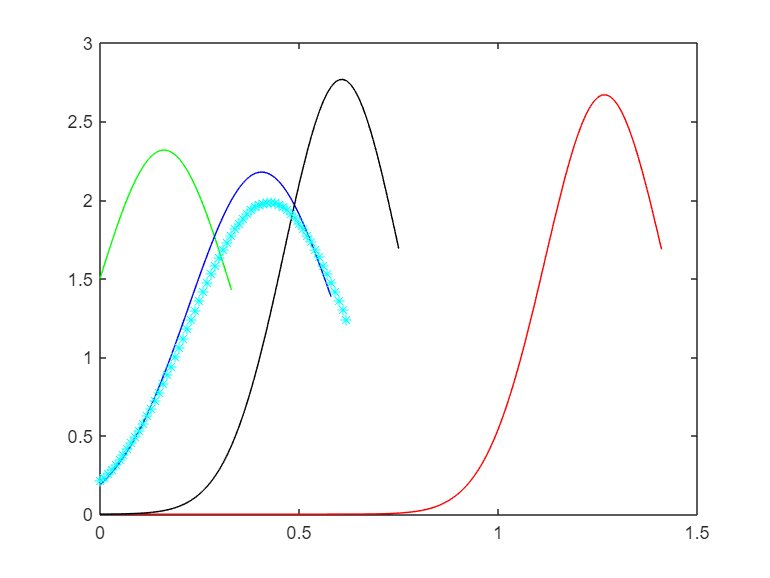

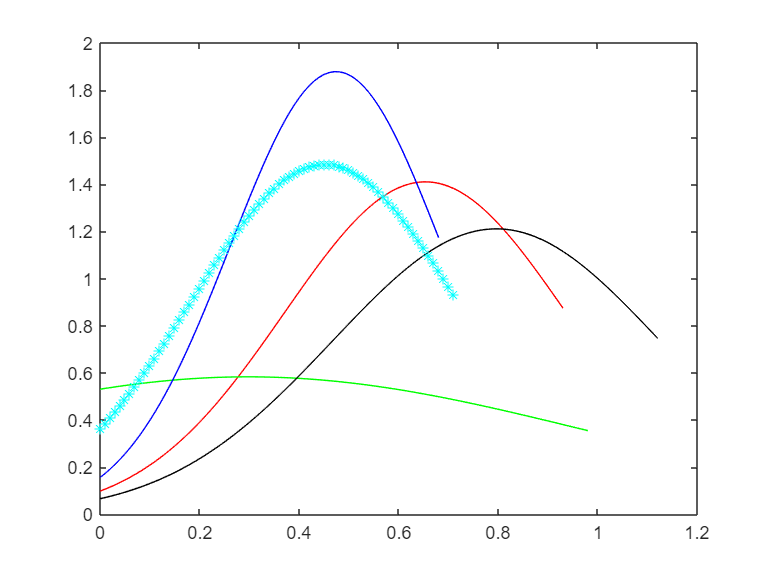

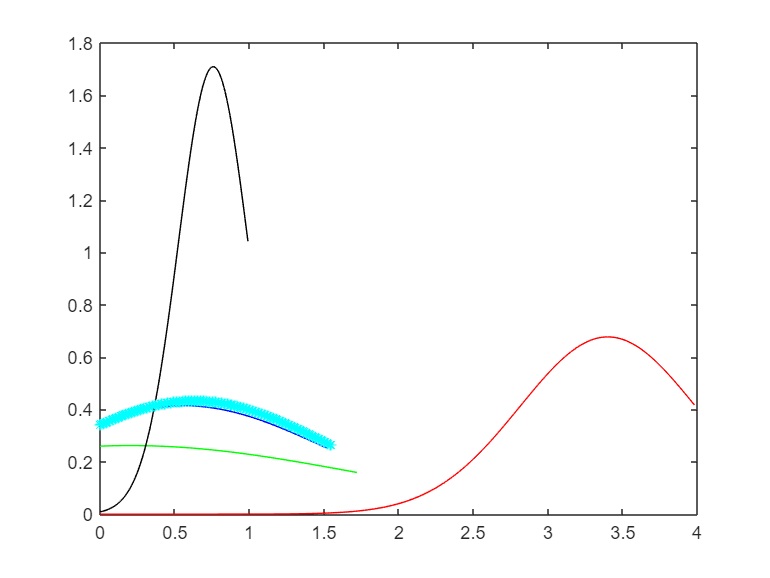

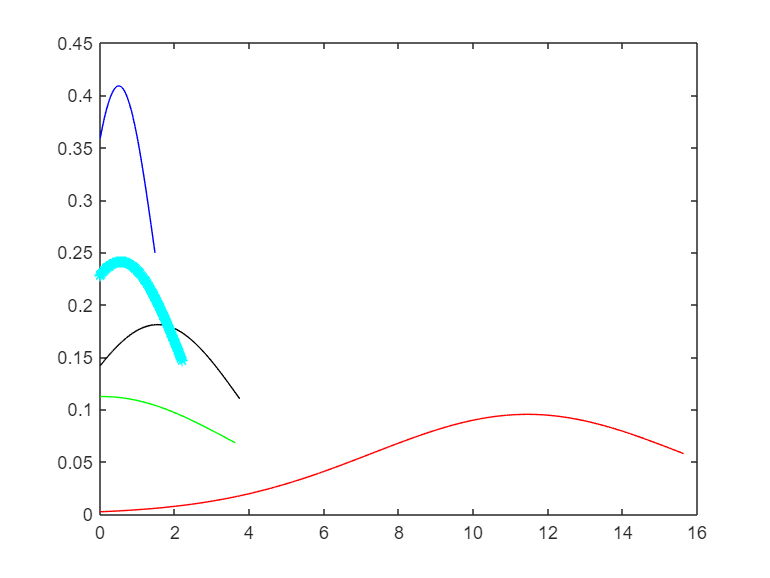


scatter(bass.holes,bass.thiness,'red')
hold on
scatter(guitar.holes,guitar.thiness,'blue')
scatter(trumpet.holes,trumpet.thiness,'black')
scatter(drumm.holes,drumm.thiness,'c')
hold off

Simple case

mu1 = mean([bass.holes', bass.circularity'])'

Unable to resolve the name bass.holes.

sigma1 = cov([bass.holes', bass.circularity'])
fitdist(drumm.holes',"Normal")
fitdist(drumm.circularity',"Normal")


holesX1=[-4 *sqrt(sigma1(1,1))+mu1(1):0.1:4 *sqrt(sigma1(1,1))+mu1(1)];
holesY1=normpdf(holesX1,mu1(1),sqrt(sigma1(1,1)));
circX1=[-4 *sqrt(sigma1(2,2))+mu1(1):0.1:4*sqrt(sigma1(2,2))+mu1(2)];
circY1=normpdf(circX1,mu1(2),sqrt(sigma1(2,2)));

x1=holesX1; x2=circX1;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

y = mvnpdf(X,mu1',sigma1);
y = reshape(y,length(x2),length(x1));

surf(x1,x2,y)
xlabel('x1')
ylabel('x2')
zlabel('Probability Density')

mu2 = mean([guitar.holes', guitar.circularity'])'
sigma2 = cov([guitar.holes', guitar.circularity'])

mu3 = mean([trumpet.holes', trumpet.circularity'])'
sigma3 = cov([trumpet.holes', trumpet.circularity'])

mu4 = mean([drumm.holes', drumm.circularity'])'
sigma4 = cov([drumm.holes', drumm.circularity'])

holesX4=[0:0.01:4 *sqrt(sigma4(1,1))+mu4(1)];
holesY4=normpdf(holesX4,mu4(1),sqrt(sigma4(1,1)));
circX4=[0:0.01:4*sqrt(sigma4(2,2))+mu4(2)];
circY4=normpdf(circX4,mu4(2),sqrt(sigma4(2,2)));

plot(holesX4,holesY4,'red')
hold on
plot(circX4,circY4,'green')
hold off


Bayers classsifaction using a gaussian distrubution

mu1 = mean([bass.holes', bass.circularity', bass.compactness', bass.elongation', bass.intensity', bass.thiness'])'

mu1 =     1.2667
    0.1604
    0.4056
    0.6069
    0.4252
    0.3208


sigma1 = cov([bass.holes', bass.circularity', bass.compactness', bass.elongation', bass.intensity', bass.thiness']);

mu2 = mean([guitar.holes', guitar.circularity', guitar.compactness', guitar.elongation', guitar.intensity', guitar.thiness'])'

mu2 =     0.6533
    0.2973
    0.4741
    0.7961
    0.4513
    0.5945


sigma2 = cov([guitar.holes', guitar.circularity', guitar.compactness', guitar.elongation', guitar.intensity', guitar.thiness']);

mu3 = mean([trumpet.holes', trumpet.circularity', trumpet.compactness', trumpet.elongation', trumpet.intensity', trumpet.thiness'])'

mu3 =     3.4000
    0.1999
    0.5590
    0.7578
    0.6348
    0.3997


sigma3 = cov([trumpet.holes', trumpet.circularity', trumpet.compactness', trumpet.elongation', trumpet.intensity', trumpet.thiness']);

mu4 = mean([drumm.holes', drumm.circularity', drumm.compactness', drumm.elongation', drumm.intensity', drumm.thiness'])'

mu4 =    11.4467
    0.0682
    0.5006
    1.5439
    0.5659
    0.1363


sigma4 = cov([drumm.holes', drumm.circularity', drumm.compactness', drumm.elongation', drumm.intensity', drumm.thiness']);

x=[10.7;0.03942603886198023;0.42626145446890934;1.559959856216465;0.07885207772396045;0.5734956036909918];
det(sigma1)

ans = -3.0350e-46

sigma1 =     2.8010   -0.0162    0.0028    0.0272    0.0647   -0.0324
   -0.0162    0.0008    0.0004    0.0002   -0.0009    0.0016
    0.0028    0.0004    0.0005    0.0000    0.0004    0.0007
    0.0272    0.0002    0.0000    0.0020   -0.0023    0.0004
    0.0647   -0.0009    0.0004   -0.0023    0.0158   -0.0018
   -0.0324    0.0016    0.0007    0.0004   -0.0018    0.0032


sigma2 =     0.6698    0.0008    0.0060    0.0041   -0.0001    0.0015
    0.0008    0.0030    0.0017    0.0050    0.0012    0.0059
    0.0060    0.0017    0.0012    0.0029    0.0006    0.0034
    0.0041    0.0050    0.0029    0.0104    0.0013    0.0100
   -0.0001    0.0012    0.0006    0.0013    0.0219    0.0025
    0.0015    0.0059    0.0034    0.0100    0.0025    0.0118







g1=1/sqrt(2*pi*det(sigma1))*exp(-0.5*(x-mu1)'*inv(sigma1)*(x-mu1))  

g1 = 0.0000e+00 - Infi

g2=1/sqrt(2*pi*det(sigma2))*exp(-0.5*(x-mu2)'*inv(sigma2)*(x-mu2))

g2 = 0

g3=1/sqrt(2*pi*det(sigma3))*exp(-0.5*(x-mu3)'*inv(sigma3)*(x-mu3))

g3 = 0

g4=1/sqrt(2*pi*det(sigma4))*exp(-0.5*(x-mu4)'*inv(sigma4)*(x-mu4))

g4 = 0.0000e+00 - Infi